% Define the data for lower limit, upper limit, and frequency
lowerLimits = [10, 15, 20, 25, 30, 35, 40, 45, 50, 55]; 
upperLimits = [15, 20, 25, 30, 35, 40, 45, 50, 55, 60]; 
frequencies = [7, 9, 27, 15, 6, 6, 5, 2, 3, 2];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

        10            15            7    
        15            20            9    
        20            25           27    
        25            30           15    
        30            35            6    
        35            40            6    
        40            45            5    
        45            50            2    
        50            55            3    
        55            60            2    




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 27.62


fprintf('Median: %.2f\n', medianValue);

Median: 22.50


fprintf('Mode: %.2f\n', modeValue);

Mode: 22.50


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 10.83


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 12.26


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: 10.24


fprintf('Karl: %.2f\n', Karl);

Karl: 0.47


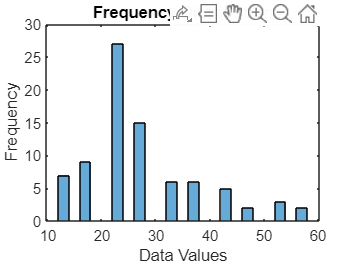


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');